clear;
for i = 1:3
    for j = 1:3
        for k = 1:5
            A(i,j,k) = i + 2*j;
        end
    end
end

A

A = A(:,:,1) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,2) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,3) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,4) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,5) =

     3     5     7
     4     6     8
     5     7     9



B = reshape(A,[],5)

B =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     7     7     7     7     7
     8     8     8     8     8
     9     9     9     9     9



clear;
M = 10;
N = ceil(M/2);
orig_dom_X = linspace(-pi/2,pi/2,M);
orig_dom_Y = linspace(-pi/2,pi/2,N)

orig_dom_Y =    -1.5708   -0.7854         0    0.7854    1.5708


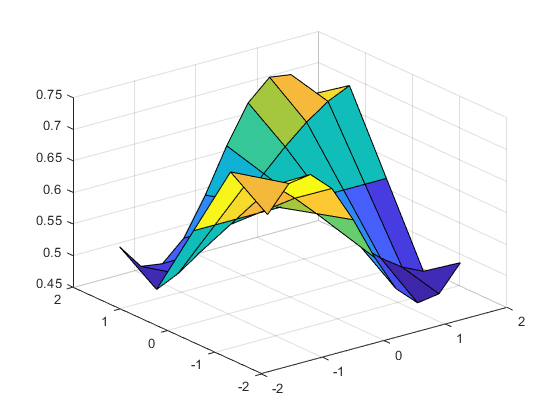

[X,Y] = ndgrid(orig_dom_X,orig_dom_Y);

for i = 1:88
    m = rand;
    b = rand;
    A(:,:,i) = m*sin(X.*Y) + b;
end
surf(X,Y,A(:,:,5))


s = size(A);

B = reshape(A,[],s(end))

B =     1.0273    0.6081    0.3807    0.3638    0.6761    0.2480    0.4874    0.4938    0.8829    0.7023    1.0754    0.8021    1.1021    0.8969    0.7816    1.0492    1.2881    0.4218    1.0795    0.2808    0.2214    1.5910    1.1014    0.6468    0.7070    0.2683    1.0551    0.6382    0.5490    1.2561    0.2497    0.7672    0.3893    0.8009    0.7252    0.7700    0.7201    0.2374    1.1185    0.5507    1.0634    0.9881    0.6196    1.2912    1.0419    1.0563    0.7159    1.0786    0.8022    1.2061
    1.2969    0.8754    0.5402    0.4989    0.7163    0.3194    0.5569    0.6414    1.0850    0.8618    1.3260    0.8533    1.4066    1.1777    0.9606    1.1871    1.4572    0.5936    1.1952    0.4091    0.2995    1.9048    1.3540    0.8883    0.7995    0.3809    1.3655    0.7973    0.6310    1.5188    0.3695    1.0189    0.5732    1.0100    0.8821    0.8808    1.0273    0.3362    1.3516    0.6185    1.2667    1.0419    0.8652    1.5655    1.2940    1.1260    0.9028    1.1619    0.9347    1

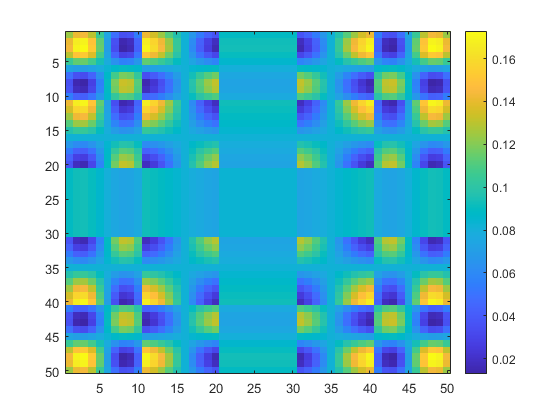

B = B';

C_B = cov(B);
imagesc(C_B)
colorbar


% 'If I reshape this^ image correctly, I should get a 4D array that varies smoothly on each of its 4 axes'
disp(['If I reshape this^ image correctly,' newline 'I should get a 4D array that ' newline 'varies smoothly on each of its 4 axes.'])

If I reshape this^ image correctly,
I should get a 4D array that 
varies smoothly on each of its 4 axes.



disp(['A good way to check if I''m reshaping it' newline 'properly or not would be to' newline 'reshape, interpolate, reshape, and plot.'])

A good way to check if I'm reshaping it
properly or not would be to
reshape, interpolate, reshape, and plot.



C = reshape(C_B,M,N,M,N);
disp('size of C')

size of C


size(C)

ans =     10     5    10     5


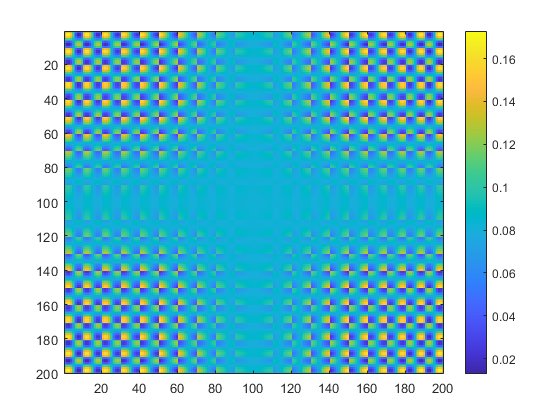


N_h = 2*N;
M_h = 2*M;
new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(-pi/2,pi/2,M_h);
new_dom_X2 = linspace(-pi/2,pi/2,N_h);
new_dom_Y2 = linspace(-pi/2,pi/2,M_h);

[X1_h,Y1_h,X2_h,Y2_h] = ndgrid(new_dom_X1,new_dom_Y1,new_dom_X2,new_dom_Y2);
C_high_def = interpn(orig_dom_X,orig_dom_Y,orig_dom_X,orig_dom_Y,C,X1_h,Y1_h,X2_h,Y2_h);
C_B_high_def = reshape(C_high_def,N_h*M_h,N_h*M_h);



imagesc(C_B_high_def)
colorbar


disp('This is awesome and meta.')

This is awesome and meta.
